% Jep Brinkmann Thesis HMM example
clc; close all;
k = 5;
d = 30;

options.method = "random_no_offset";
options.lambda = 5;

T_seq = 1e5;
m = 1000;

covNorm = zeros(2, m);
Cost = zeros(2, m);

for i = progress(1:m)
    [T, O, pi, k, d] = generateHMM(k, d, 1, options);
    covNorm(1, i) = sum(corrcoef(O) - eye(k), "all");

    [seq, ~] = generate_hmm_sequence(T, O, pi, T_seq);
    [P3_n, ~] = estimate_joint_prob(seq, d, P3_inf);
    [Uhat, ~] = cpd(P3_n, k);
    
    B1 = Stochasticize(Uhat{1});
    B2 = Stochasticize(Uhat{2});
    B3 = Stochasticize(Uhat{3});
    
    [T_hat, O_hat, pi_hat] = FactorMatrices2HMM({B1, B2, B3});
    [T_hat, O_hat, pi_hat] = remove_hmm_permutation_transition(T, T_hat, O_hat, pi_hat);

    Cost(1, i) = norm(T - T_hat, "fro") + norm(O - O_hat, "fro");
end

Processing:  000%  |                                    | 0/1000it [00:00:00<Inf:NaN:NaN, Inf it/s]


options.method = "random";

for i = progress(1:m)
    [T, O, pi, k, d] = generateHMM(k, d, 1, options);
    covNorm(2, i) = sum(corrcoef(O) - eye(k), "all");

    [seq, ~] = generate_hmm_sequence(T, O, pi, T_seq);
    [P3_n, ~] = estimate_joint_prob(seq, d, P3_inf);
    [Uhat, ~] = cpd(P3_n, k);
    
    B1 = Stochasticize(Uhat{1});
    B2 = Stochasticize(Uhat{2});
    B3 = Stochasticize(Uhat{3});
    
    [T_hat, O_hat, pi_hat] = FactorMatrices2HMM({B1, B2, B3});
    [T_hat, O_hat, pi_hat] = remove_hmm_permutation_transition(T, T_hat, O_hat, pi_hat);

    Cost(2, i) = norm(T - T_hat, "fro") + norm(O - O_hat, "fro");
end

Processing:  000%  |                                    | 0/1000it [00:00:00<Inf:NaN:NaN, Inf it/s]


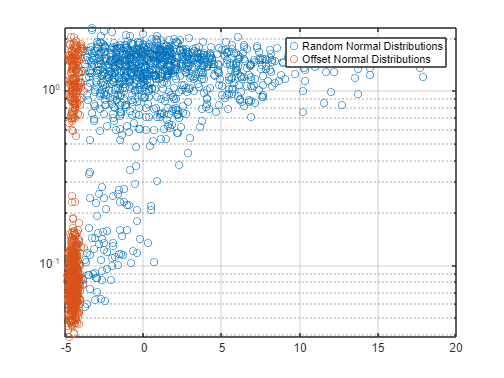


figure()
semilogy(covNorm', Cost', 'o')
grid on; legend("Random Normal Distributions", "Offset Normal Distributions")